# Coins Project

clc; clear all; close all;

## Directories 

% Set working directory
cd('Coins Project')
% Add path to bias, dark and flat images
addpath src/
addpath images/DIIP-images-bias/DIIP-images/Bias/
addpath images/DIIP-images-dark/DIIP-images/Dark/
addpath images/DIIP-images-flat/DIIP-images/Flat/

% Add path to raw images
addpath images/DIIP-images-measurements-1/DIIP-images/Measurements/
addpath images/DIIP-images-measurements-2/DIIP-images/Measurements/

##  Means of bias, dark, and flat images

biasImagesFolder = "images/DIIP-images-bias/DIIP-images/Bias";
darkImagesFolder = "images/DIIP-images-dark/DIIP-images/Dark";
flatImagesFolder = "images/DIIP-images-flat/DIIP-images/Flat";
[meanBias, meanDark, normFlat] = imagesMeans(biasImagesFolder, darkImagesFolder, flatImagesFolder)

meanBias = 2592×3872×3 uint8 array
meanBias(:,:,1) =

    4    5    3    3    4    4    4    3    3    4    4    3    3    3    4    5    5    5    4    5    5    4    4    4    4    4    4    3    3    3    3    3    3    3    3    3    4    4    3    4    3    3    2    3    4    3    3    3    4    4    4    4    4    4    6    5    4    3    3    3    3    3    3    4    4    4    3    4    4    4    4    4    3    3    3    3    3    3    3    4    3    3    4    4    3    3    4    3    4    3    3    3    3    3    3    4    4    4    3    3    3    3    3    4    4    4    4    4    3    3    2    3    4    4    4    4    3    3    3    4    4    5    4    4    4    3    3    3    4    3    3    4    4    3    4    5    4    4    3    4    5    4    4    4    4    3    3    3    3    4    4    5    4    4    4    3    4    4    3    2    3    4    5    5    4    3    3    4    4    4    4    4    4    3    4    4    4    4    4    4    4    4    4    3    4    4    4    3    4 

meanDark = 2592×3872×3 uint8 array
meanDark(:,:,1) =

    0    0    1    1    0    1    1    2    1    0    0    1    0    0    0    0    0    0    0    0    0    1    0    1    0    0    0    0    0    1    1    1    1    2    1    1    0    1    1    1    1    0    0    0    1    2    1    2    1    1    0    1    1    1    0    0    0    2    0    0    0    0    1    0    1    1    1    0    0    1    1    1    1    0    0    1    1    1    1    1    1    1    0    1    1    1    0    0    0    1    1    0    1    1    0    0    0    0    0    1    1    1    1    0    0    0    0    1    1    1    1    0    0    0    1    0    1    2    1    1    0    0    0    0    1    1    1    1    0    0    0    0    0    1    0    1    1    0    0    0    0    0    0    0    1    2    1    1    1    1    1    0    0    0    0    1    0    0    0    1    1    0    0    0    0    0    1    0    0    0    0    0    1    1    0    0    0    0    1    0    1    1    1    1    0    0    0    1    0 

normFlat = 2592×3872×3 uint8 array
normFlat(:,:,1) =

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

## Intensity Calibration

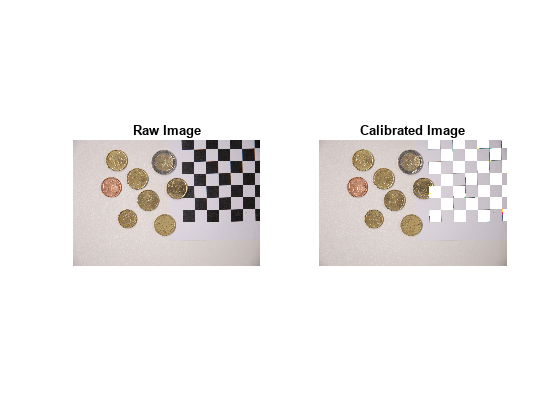

image_name = '_DSC1774.JPG';
measurement = imread(image_name);
calibrated_image = (measurement - meanBias - meanDark) ./ normFlat;
figure(1);
subplot(121); imshow(uint8(measurement)); title('Raw Image');
subplot(122);imshow(uint8(calibrated_image)); title('Calibrated Image');

[checkerboardPoints, boardSize] = detectCheckerboardPoints(measurement, 'PartialDetections', false);

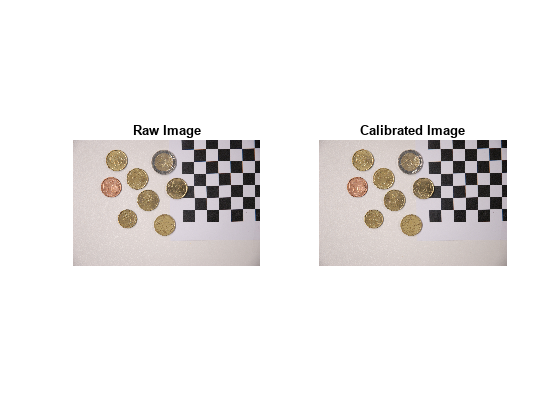

I = calibrateIntensity(measurement, meanBias, meanDark, normFlat, checkerboardPoints, boardSize);
figure(2);
subplot(121); imshow(uint8(measurement)); title('Raw Image');
subplot(122); imshow(I); title('Calibrated Image');

## Image Segmentation

% rgb = imread("_DSC1772.JPG");
% imshow(rgb)
% d = drawline;
% pos = d.Position;
% diffPos = diff(pos);
% diameter = hypot(diffPos(1),diffPos(2))

## Run Final Function

% Detect coins in a calibrated image.
g = ["_DSC1772.JPG" "_DSC1773.JPG" '_DSC1774.JPG' '_DSC1775.JPG' '_DSC1776.JPG' '_DSC1777.JPG' '_DSC1778.JPG' '_DSC1779.JPG' '_DSC1780.JPG' '_DSC1781.JPG' '_DSC1782.JPG' '_DSC1783.JPG'];
% g = ["_DSC1772.JPG"];
for i=1:length(g)
    measurement = imread(g(i));
    coins = estim_coins(measurement, meanBias, meanDark, normFlat);
    disp(coins);
end

     0     0     0     0   372     0



     0     0     0     0    79     0



     0     0     0     0   225     0



     0     0     0     0   446     0



     0     0     0     0   106     0



     0     0     0     0   347     0



     0     0     0     0   405     0



     0    17     0     0   167     0



     0     0     0     0    27     0



     0     0     0     0   316     0



     0     1     0     0   112     0



     0     0     0     0   237     0

